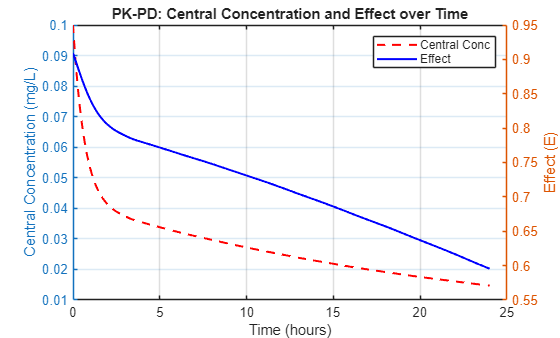

clear

% Parameters
D = 10;
CL = 10;
V(1) = 100;      % Central volume
Q = 80;          % Intercompartmental clearance
V(2) = 120;      % Peripheral volume

t = 0:0.1:24;
tspan = [0 24];

% PD Parameter
Emax = 1;
n=1;
EC50=0.01;

% List THETA
THETA = [CL, V(1), Q, V(2)];

% Initial Amounts (IV bolus into central)
Initial_Conc = [D/V(1), 0];

% ODE Options
options = odeset();

% Solve ODE
sol = ode23(@WK3_Class_4_103, tspan, Initial_Conc, options, THETA);

% Evaluate solution
Csol = deval(sol, t);

% Extract amounts
C1 = Csol(1, :);   % Central
C2 = Csol(2, :);   % Peripheral

% PK/PD
E = (Emax*C1.^n)./(EC50^n + C1.^n);

% ======= PK-PD Plot (merged) =======

figure('Color','w');

% Plot Central Concentration and Effect on the same axes
yyaxis left
plot(t, C1, '--r', 'LineWidth', 1.5)   % PK: Central concentration
ylabel('Central Concentration (mg/L)')
xlabel('Time (hours)')
grid on

yyaxis right
plot(t, E, '-b', 'LineWidth', 1.5)     % PD: Effect
ylabel('Effect (E)')

title('PK-PD: Central Concentration and Effect over Time')
legend({'Central Conc','Effect'}, 'Location','northeast')


figure('Color','w');

yyaxis left
plot(t, C1, '--r', 'LineWidth', 1.5)   % Central
hold on
plot(t, C2, '--m', 'LineWidth', 1.5)   % Peripheral
ylabel('Concentration (mg/L)')
xlabel('Time (hours)')
grid on

yyaxis right
plot(t, E, '-b', 'LineWidth', 1.5)     % Effect
ylabel('Effect (E)')

title('PK-PD: Central & Peripheral Concentration and Effect over Time')
legend({'Central Conc','Peripheral Conc','Effect'}, 'Location','northeast')